data = load("resultadosCSV_3M3.txt");
length(data)

ans = 10240


stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start = 27

n_max_start = 335

n_max_start = 335

T           = 5e-9;
load('DatosCalibracion.mat');

T_buscado = 1/(2*3.3e6)

T_buscado = 1.5152e-07

T_buscado/T

ans = 30.3030


T_buscado - 30*T

ans = 1.5152e-09

tiempo_muerto = 15*5e-9

tiempo_muerto = 7.5000e-08

% t_fino = (start)*tau_start - (stop)*tau_stop;
% t_fino = (start-stop)*tau_stop;
t_fino = cal_start(start) - cal_stop(stop)

t_fino = 	1.0e+-8 *

   -0.3068    0.1874    0.1868   -0.3127    0.1881   -0.3071    0.1920    0.1882   -0.3102    0.1859   -0.3122    0.1888    0.1917   -0.3100    0.1926   -0.3096    0.1907    0.1888   -0.3106    0.1897   -0.3100    0.1906    0.1893   -0.3101    0.1891    0.1911    0.1891    0.1896   -0.3099    0.1873    0.1879   -0.3110    0.1878   -0.3116    0.1875    0.1907   -0.3119    0.1920   -0.3097    0.1923    0.1905   -0.3109    0.1859   -0.3078    0.1888    0.1938   -0.3091    0.1912   -0.3125    0.1881


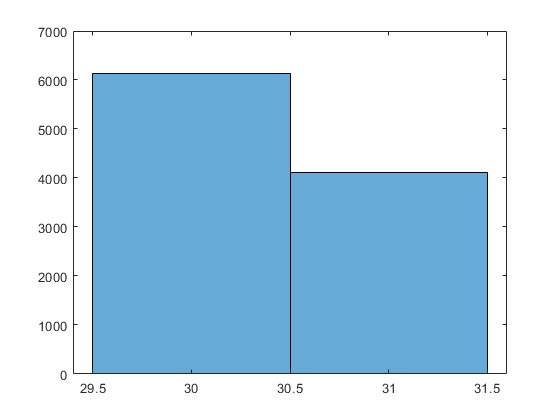

t = (coarse*T) + t_fino;

histogram(coarse)

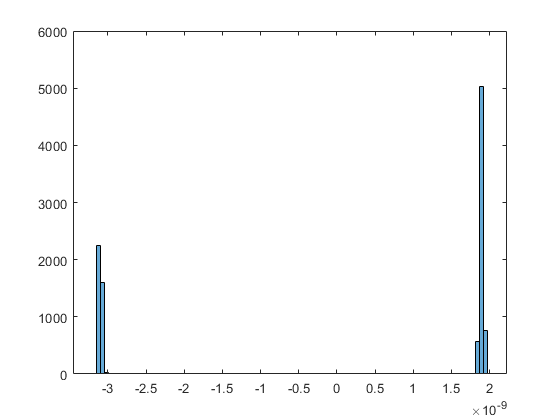

histogram(t_fino,100)

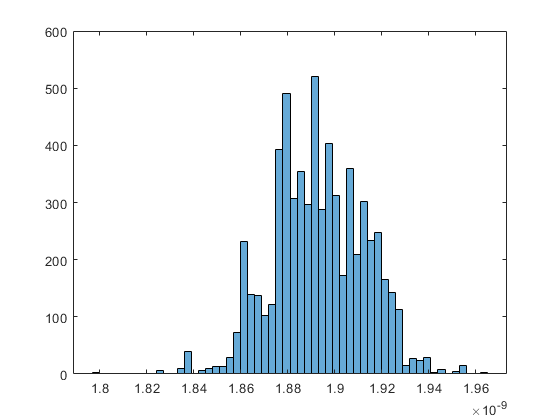

histogram(t_fino(t_fino>0))


histogram(t_)

Unrecognized function or variable 't_'.

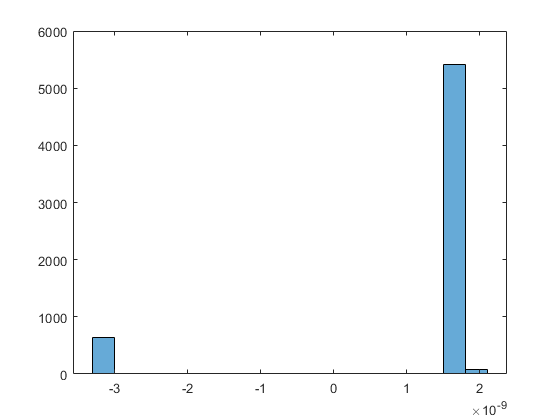

%%30 cuentas
%%a estos malos hay que sumarles un T
indices_30 = find(coarse==30);
start_30 = start(indices_30);
stop_30 = stop(indices_30);
fino_30 = t_fino(indices_30);
coarse_30 = coarse(indices_30);
histogram(fino_30);

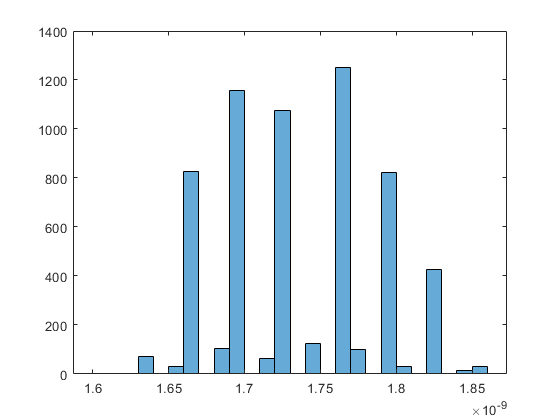

fino_30_buenos = fino_30(fino_30>0);
start_30_buenos = start_30(fino_30>0);
stop_30_buenos  = stop_30(fino_30>0);
coarse_30_buenos = coarse_30(fino_30>0);
fino_30_malos  = fino_30(fino_30<=0);
coarse_30_malos = coarse_30(fino_30<0);
histogram([fino_30_buenos; fino_30_malos+T])

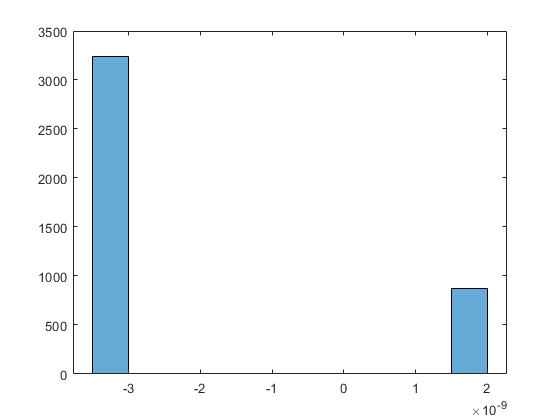

% find(t_fino<=0)

%%31 cuentas
%%a estos malos hay que restarles un T
indices_31 = find(coarse==31);
fino_31 = t_fino(indices_31);
coarse_31 = coarse(indices_31);
histogram(fino_31);

fino_31_buenos = fino_31(fino_31<0);
coarse_31_buenos = coarse_31(fino_31<0);
fino_31_malos  = fino_31(fino_31>=0);
coarse_31_malos = coarse_31(fino_31>0);

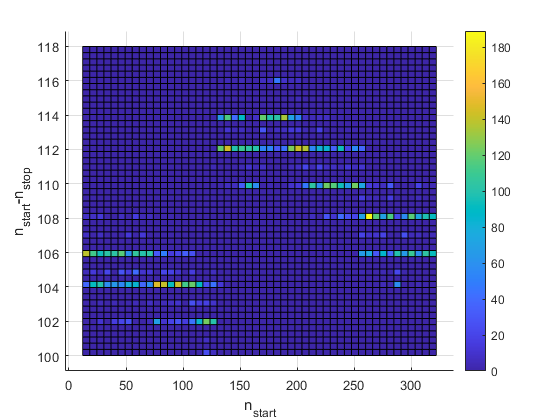

st = start-stop;
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
% std(st_positivo)
hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_3M3.eps');

tiempos = cal_start(start_30_buenos)-cal_stop(stop_30_buenos)

Unrecognized function or variable 'cal_start'.

histogram(tiempos, 100);
mean(tiempos)
T_buscado
error = 30*T + mean(tiempos) - T_buscado 
std(tiempos)

clf;
y = [fino_30_buenos; fino_30_malos+T; fino_31_buenos+T; fino_31_malos];
histogram(y)
presicion = std(y)
media     = mean(y)
coarse_correcto = 30;
N = 100;
length(y)
length(fino_30_malos)
length(fino_31_buenos)

% Preallocate arrays for bin edges and counts
binEdges = [];
counts = zeros(4, N);  % Assuming there are 4 data vectors

% Calculate histograms
%%cuidado acá! los finos_31 deberían dar una medición fina negativa (~-3)
%%pero sumo T a los buenos y nada a los malos para hacerlos positivos, y
%%juntarlos con las mediciones buenas
data = {fino_30_buenos, (fino_30_malos+T), fino_31_buenos+T, fino_31_malos};
for i = 1:4
    h = histogram(data{i}, N, 'Visible', 'off');
    binEdges = h.BinEdges;
    counts(i, :) = h.BinCounts;
end

% Create common bin edges
commonEdges = linspace(min(binEdges), max(binEdges), N+1);

% Recalculate counts using common edges
for i = 1:4
    counts(i, :) = histcounts(data{i}, commonEdges);
end

% Combine the counts into a matrix
countsMatrix = counts';

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo[s]');
ylabel('Frecuencia ');
legend({'Fino 30', 'Fino 30(*)', 'Fino 31', 'Fino 31(*)'});
% title('Stacked Histogram of Different Data Groups');
exportgraphics(gcf,'histograma_3M3.eps');
fino_buscado = T_buscado - 30*T
error = 30*T + media - T_buscado

clf;

% Data vectors
data = {coarse_30_buenos, coarse_30_malos, coarse_31_buenos, coarse_31_malos};

% Number of bins
N = 8;

% Create common bin edges
commonEdges = 29.5:0.25:31.5

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({'Grueso 30', 'Grueso 30(*)', 'Grueso 31', 'Grueso 31(*)'});
exportgraphics(gcf,'histograma_coarse_3M3.eps');